# Converting Between Color Spaces

Now that you've been introduced to different color spaces, let's practice converting between them. This is a first step to thresholding color images or adjusting the contrast of color images, which you will learn about later in this course. Work through this script section by section to practice converting an image from RGB to alternative color spaces and back to RGB.

### Import and display a color image

Run this section to read in an image of an ice shelf and display it.

img = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
imshow(img)

### Convert to alternative color spaces

Uncomment the lines of code below and convert the image to alternative color spaces. Use the variable names provided as they will be used in the rest of this script.

Convert to HSV

% hsvImg = 

Convert to YCbCr

% ycbcrImg = 

Convert to L*a*b*

% labImg = 

### Examine the matrix values and data types

The code below extracts the values at the top left hand corner of the third color plane for all four images. Examine the results. 

img(1:10,1:10,3)
hsvImg(1:10,1:10,3)
ycbcrImg(1:10,1:10,3)
labImg(1:10,1:10,3)

The results look completely different! Also, take a look at the workspace to see the different data types of the matrices. 

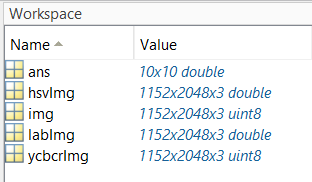

Notice how the original image and the YCbCr representation are both of type uint8, but the HSV and L*a*b* values are of type double. This is important to remember as you perform your own color space conversions.

### Display the converted images

Finally, show all the converted images just to make sure they still look the same.

imshow(hsvImg)
imshow(ycbcrImg)
imshow(labImg)

Oh no! This doesn't look right! What happened?

### Display the image correctly in RGB

The `imshow` function only interprets images in the RGB color space. It does, however, accept matrices of different data types, including both uint8 and double, which is why we were able to run `imshow` with the HSV and L*a*b* images. 

*Always convert back to RGB* when working with images in different color spaces before displaying them.

Uncomment the lines below to convert the images back to RGB.

Convert from HSV to RGB

% rgbImg1 =

Convert from YCbCr to RGB

% rgbImg2 = 

Convert from L*a*b* to RGB

% rgbImg3 = 

Display the images again.

imshow(rgbImg1)
imshow(rgbImg2)
imshow(rgbImg3)

That's much better! All of these images look identical to the original image. Do note that changing the images back to RGB does not change their datatypes, so two of the three new RGB images are of type double. 

*Copyright 2022 The MathWorks, Inc.*